# Radar Signal Processing Verification

This script has been written to confirm that the signal processing component of a radar is working as anticipated

## Initialize the simulator

clear;
simulator = Simulator_revB();
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
% file_path = "B210_params.json";
% file_path = "B210_params_highBW.json";
% file_path = "B210_params_highvres.json";
% file_path = "B210_params_lowBW.json";
% file_path = "B210_params_sensing_system.json";
 file_path = "X310_params_100MHzBW.json";
% file_path = "realistic_params.json";
% file_path = "realistic_long_range.json";
simulator.load_params_from_JSON(david_path + file_path);


%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 1.50 GHz
	 Frequency Slope: 		 2.13 MHz/us
	 Idle Time: 			 3.12 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.88 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 1.60 MSps
	 Ramp End Time: 		 46.88 us
	 Chirp Tx Bandwidth: 		 99.84 MHz
	 Chirp Sampling Bandwidth: 	 85.20 MHz
	 ADC Sampling Period: 		 40.00 us
	 Chirp Cycle Time: 		 50.00 us
	 Chirp Wavelength: 		 199.86 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 12.80 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 112.60 m
	 Range Resolution 		 1.76 m
	 Max Velocity 			 999.31 m/s
	 Velocity Resolution 		 7.81 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 100.80 MHz
	 Downsampling factor 		 63
	 Sweep time 			 46.88 us
	 Samples per chirp 		 5040.00 


## Initialize the Target

simulator.load_target_realistic(126,36);

## Initialize the Victim and Simulation Parameters

%specify the number of frames and chirps to compute
frames_to_compute = 10;

%specify whether or not to record a move of the range-doppler plot
record_movie = true;
simulator.Victim.Radar_Signal_Processor.configure_movie_capture(frames_to_compute,record_movie);

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

## Initialize the Attacker

%initialize the attacker parameters
simulator.Attacker.initialize_attacker(...
                        simulator.Victim.FMCW_sampling_rate_Hz * 1e-6,...
                        simulator.Victim.StartFrequency_GHz,...
                        simulator.Victim.Chirp_Tx_Bandwidth_MHz);

%initialize the sensing subsystem's debugger
simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(0,simulator.Victim,frames_to_compute);
%set to change 1 to zero to disable

%specify the type of emulation ("target", 
        % "velocity spoof - noisy", 
        % "velocity spoof - similar velocity",
        % "range spoof - similar slope")

%attack_type = "range spoof - similar slope";
attack_type = "velocity spoof - similar velocity,range spoof - similar slope ";
%initialize the attacker
simulator.Attacker.Subsystem_attacking.set_attack_mode(attack_type);

%if it is desired to specify a specific attack location
% simulator.Attacker.Subsystem_attacking.set_desired_attack_location(75,7);

## Run the Simulation

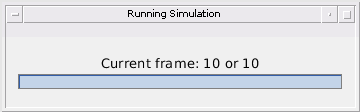

%run the simulation (without an attacker for now)
simulator.run_simulation_with_attack(frames_to_compute,true);

## Results

%get the estimated ranges and velocities
simulator.Victim.Radar_Signal_Processor.range_estimates

ans =   126.1086       NaN       NaN       NaN       NaN
  127.2489       NaN       NaN       NaN       NaN
  128.3456       NaN       NaN       NaN       NaN
  129.5360       NaN       NaN       NaN       NaN
  130.6514       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


simulator.Victim.Radar_Signal_Processor.velocity_estimates

ans =   -33.8730       NaN       NaN       NaN       NaN
  -33.7031       NaN       NaN       NaN       NaN
  -33.8995       NaN       NaN       NaN       NaN
  -33.8343       NaN       NaN       NaN       NaN
  -33.6805       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


%play the movie for the range doppler
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_range_doppler_movie();
end

%play the movie for the clusters
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_clustering_movie()
end

Generate plot of IF signals

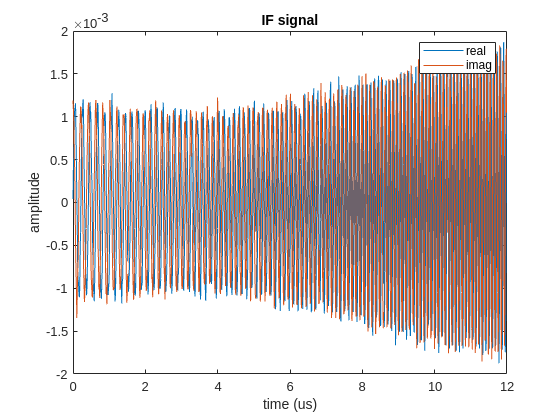

sampled_IF_sig = simulator.Victim.Radar_Signal_Processor.radar_cube(:,1);
inter_sample_period = 1/simulator.Victim.ADC_SampleRate_MSps;
times = 0:inter_sample_period:(simulator.Victim.ADC_Samples - 1) * inter_sample_period;
clf;
plot(times,real(sampled_IF_sig),times, imag(sampled_IF_sig));
legend("real","imag")
xlabel("time (us)")
ylabel("amplitude")
title("IF signal")

Plot a range FFT

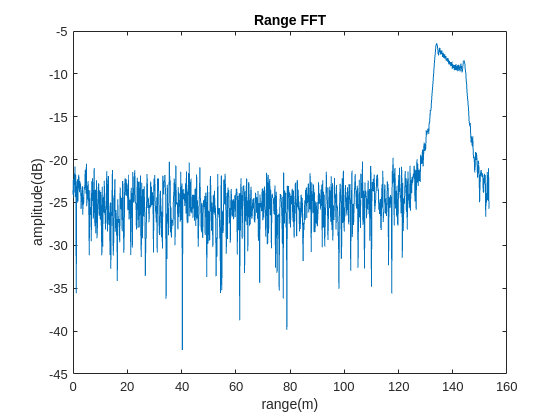

ranges = simulator.Victim.Ranges;
clf;
plot(ranges,10* log10(abs(fft(sampled_IF_sig))));
xlabel("range(m)")
ylabel("amplitude(dB)")
title("Range FFT")

Generate a subplot sampling of multiple frames for a preview of the movie

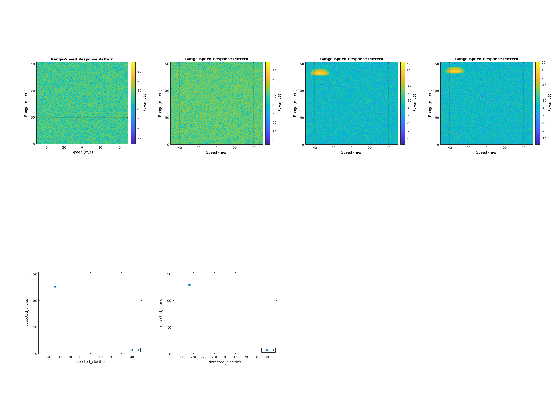

clf;
figure;
axis fill;
tiledlayout(2,4,TileSpacing="none",Padding="tight")
for i = 0:3
    %subplot of the Doppler in the left column
    nexttile
    [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_rngdop(ceil(1 + (i/4)*frames_to_compute)));
    imshow(X,map)
end
for i = 0:3
    %subplot of the clustering in the right column
    nexttile
    [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_clusters(ceil(1 + (i/4)*frames_to_compute)));
    imshow(X,map)
end

## Evaluating CFAR Performance

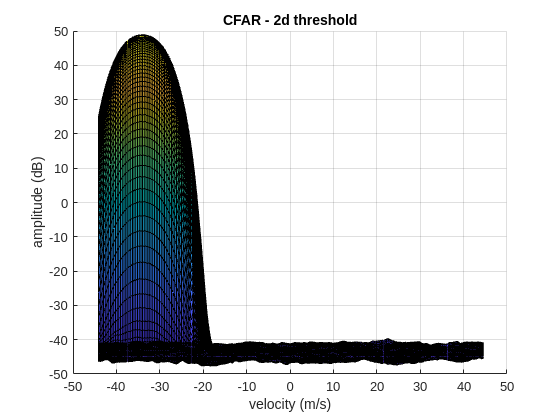

clf;
figure;

%evaluate the 2d CFAR detections for the desired frame
radar_cube = simulator.Victim.Radar_Signal_Processor.radar_cube;
[frame_resp, rnggrid,dopgrid] = simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse(radar_cube);
CUT_indicies = simulator.Victim.Radar_Signal_Processor.CUT_indicies;

%configure the CFAR
release(simulator.Victim.Radar_Signal_Processor.CFARDetector2D);
simulator.Victim.Radar_Signal_Processor.CFARDetector2D.ThresholdOutputPort = true;
simulator.Victim.Radar_Signal_Processor.CFARDetector2D.OutputFormat ="CUT result";


%compute the CFAR
[detections,th] = simulator.Victim.Radar_Signal_Processor.CFARDetector2D(abs(frame_resp).^2,simulator.Victim.Radar_Signal_Processor.CUT_indicies);

%determine range indicies in threshold detector
ranges = rnggrid(CUT_indicies(1,:)); %y
velocities = dopgrid(CUT_indicies(2,:)); %x

dopgrid_th = linspace(min(velocities), max(velocities),max(CUT_indicies(2,:)) - min(CUT_indicies(2,:) - 1));
rnggrid_th = linspace(min(ranges), max(ranges),max(CUT_indicies(1,:)) - min(CUT_indicies(1,:) - 1));
[X,Y] = meshgrid(dopgrid_th, rnggrid_th);

%convert the thresholds to db
th = 20 * log10(th);

th_surface = griddata(velocities,ranges,th,X,Y);
surf(X, Y, th_surface);
view(0,0);
title("CFAR - 2d threshold");
xlabel("velocity (m/s)");
ylabel("range (m)");
zlabel("amplitude (dB)");

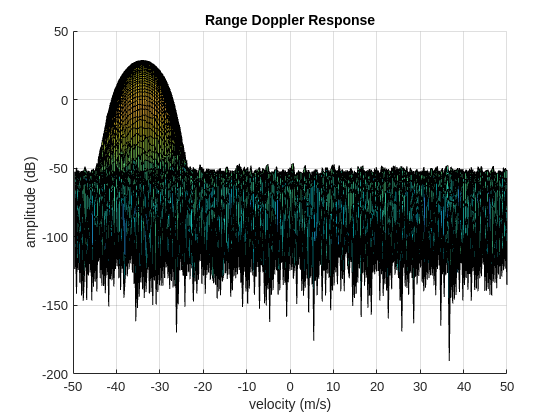


%convert the response to db
frame_resp = 20 * log10(abs(frame_resp).^2);
surf(dopgrid,rnggrid,frame_resp)
view(0,0);
title("Range Doppler Response");
xlabel("velocity (m/s)");
ylabel("range (m)");
zlabel("amplitude (dB)");

## Evaluating Range Performance

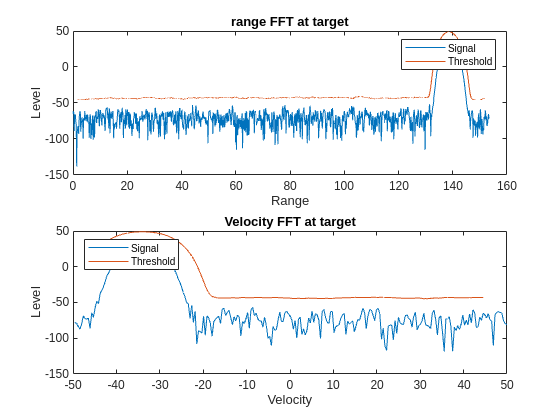

%find the maximum point
[M,I] = max(frame_resp,[],'all');
[rng_idx,vel_idx] = find(frame_resp == M);

%compute the indicies for the computed threshold
rng_idx_th = find(abs(rnggrid_th - rnggrid(rng_idx)) < 1e-4);
vel_idx_th = find(abs(dopgrid_th - dopgrid(vel_idx)) < 1e-4);

%plot range
rng_fft = frame_resp(:,vel_idx);
rng_th = th_surface(:,vel_idx_th);

subplot(2,1,1) 
plot(rnggrid,rng_fft,rnggrid_th,rng_th)
legend('Signal','Threshold','Location','Northeast')
xlabel('Range')
ylabel('Level')
title("range FFT at target")
%plot velocity
dop_fft = frame_resp(rng_idx,:);
dop_th = th_surface(rng_idx_th,:);

subplot(2,1,2) 
plot(dopgrid,dop_fft,dopgrid_th,dop_th)
legend('Signal','Threshold','Location','northwest')
xlabel('Velocity')
ylabel('Level')
title("Velocity FFT at target")